## Parámetros

rotacion = pi/4; %pi/4
factor = 4/3; %1 a 4/3
lmin = 15;
es = 3.5;
hojas = 4;
n = 300;
v = 5; %[cm/s]

lcx = 22;
lcy = 9;

q10 = 180*(pi/180);
q20 = -165*(pi/180);

%Valores iniciales de los angulos
q10i = q10;
q20i = q20;

Ttotal = (4*lmin)/v;
tt = linspace(0,Ttotal,n);

l1 = 19;
l2 = 18;

## Trébol estilizado

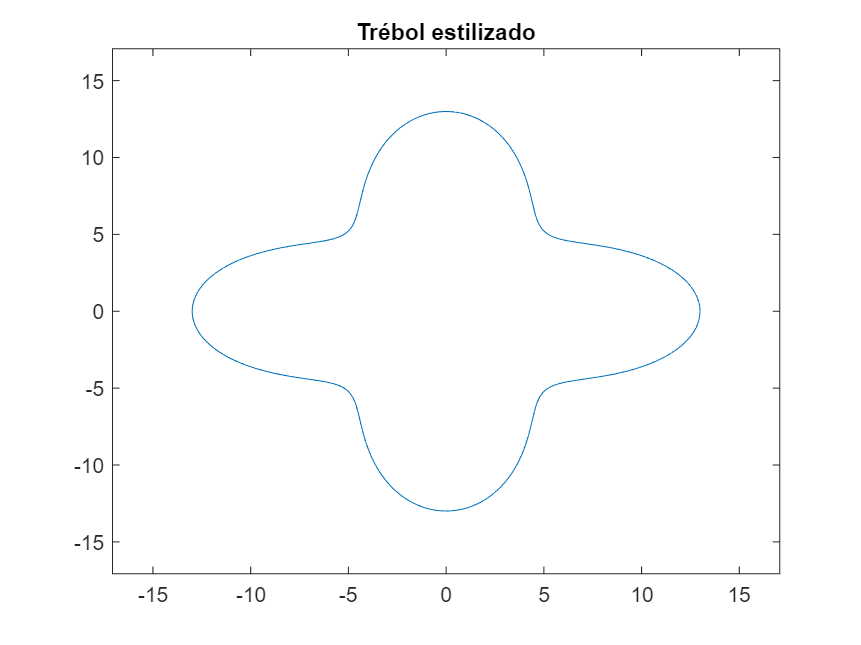

[r,theta]=trayectoria0(rotacion,lmin, factor,es,hojas,n);

xp = r.*cos(theta);
yp = r.*sin(theta);
plot(xp,yp)
title('Trébol estilizado')
a = ((lmin/2)*factor)*(1+sin(rotacion));
xlim ([-a a])
ylim ([-a a])

## Trasladando al origen

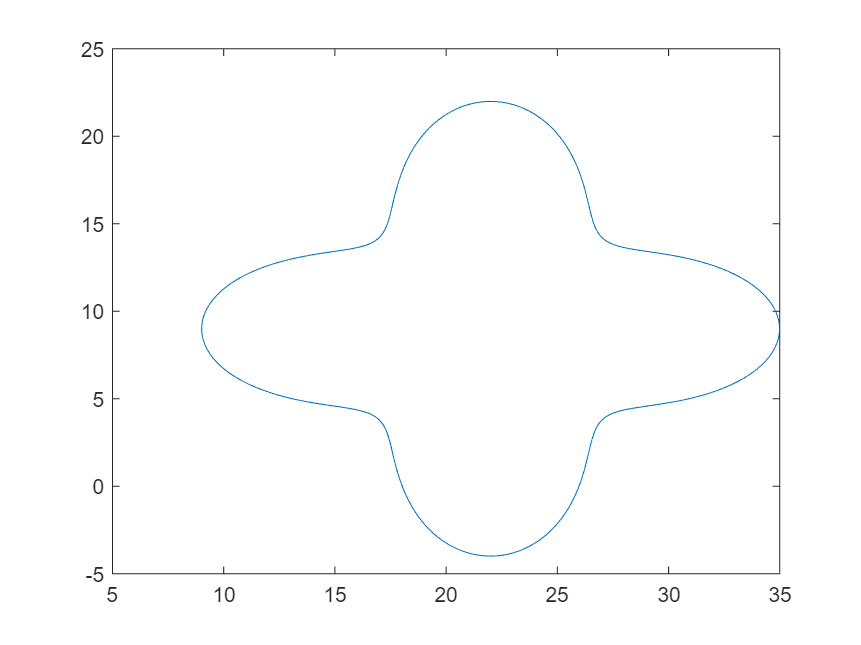

[x,y]=Totrigen(lcx,lcy,theta,r);
plot(x,y)

## Cinemática inversa

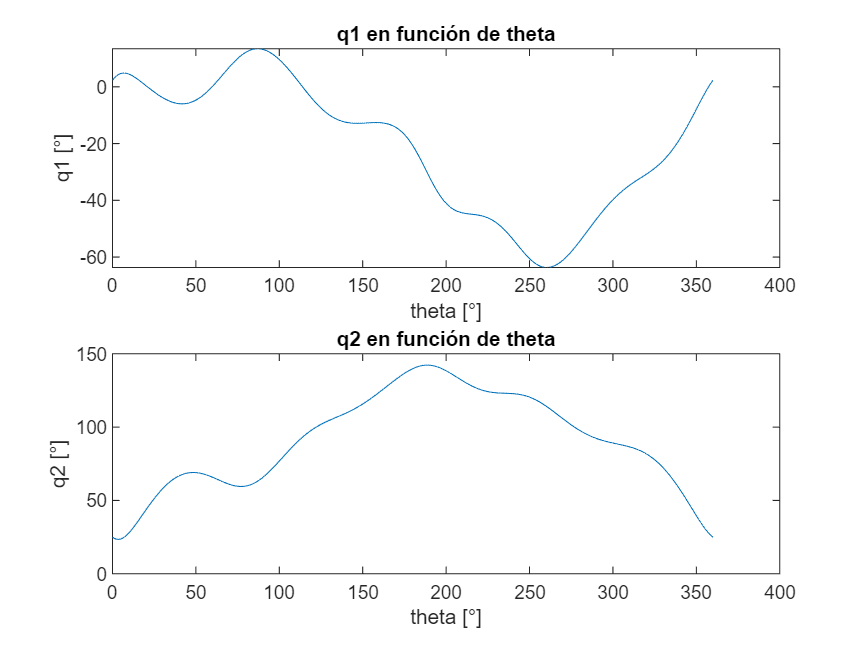

q1 = zeros(length(x),1);
q2 = zeros(length(x),1);
for i = 1:length(x)
    [q1(i), q2(i)] = Cinversa(l1,l2,x(i),y(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
end

figure()
subplot(2,1,1);
plot((theta)*(180/pi),q1*(180/pi))
title('q1 en función de theta')
ylabel('q1 [°]')
xlabel('theta [°]')

subplot(2,1,2); 
plot(theta*(180/pi),q2*(180/pi))
title('q2 en función de theta')
ylabel('q2 [°]')
xlabel('theta [°]')

## Trayectoria de acercamiento

[x20, y20] = Cdirecta(l1,l2,q10i,q20i); %Posición inicial extremo distal
[distPoint] = sqrt((x-x20).^2+(y-y20).^2);
minimo = min(distPoint)

minimo = 11.3028

pos = find(distPoint==minimo,1)

pos = 154

distPoint(pos);
%pos = (n/2) + 1; %Aprox en pi
[x2f, y2f] = Totrigen(lcx,lcy,theta(pos),r(pos));
Xaprox = linspace(x20,x2f,100);
Yaprox = linspace(y20,y2f,100);
% figure()
% hold on
% plot(Xaprox,Yaprox)
% plot(x,y)
% hold off

## Perfil trapezoidal Acercamiento

deltaX = x2f-x20

deltaX = 10.7807

deltaY = y2f-y20

deltaY = 3.3957

t = 5; %s
t1 = t/3; %Perfiles con tiempos iguales
VcX = (0.5*deltaX)/t1;
VcY = (0.5*deltaY)/t1;

t = linspace(0,t,100);

mX = VcX/t1;
mY = VcY/t1;
Vx = mX*t-mX*(t-t1).*(t>=t1)-mX*(t-2*t1).*(t>=2*t1)

Vx =          0    0.0980    0.1960    0.2940    0.3920    0.4900    0.5880    0.6860    0.7840    0.8821    0.9801    1.0781    1.1761    1.2741    1.3721    1.4701    1.5681    1.6661    1.7641    1.8621    1.9601    2.0581    2.1561    2.2541    2.3521    2.4501    2.5482    2.6462    2.7442    2.8422    2.9402    3.0382    3.1362    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342    3.2342


Vy = mY*t-mY*(t-t1).*(t>=t1)-mY*(t-2*t1).*(t>=2*t1)

Vy =          0    0.0309    0.0617    0.0926    0.1235    0.1544    0.1852    0.2161    0.2470    0.2778    0.3087    0.3396    0.3704    0.4013    0.4322    0.4631    0.4939    0.5248    0.5557    0.5865    0.6174    0.6483    0.6791    0.7100    0.7409    0.7718    0.8026    0.8335    0.8644    0.8952    0.9261    0.9570    0.9878    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187    1.0187


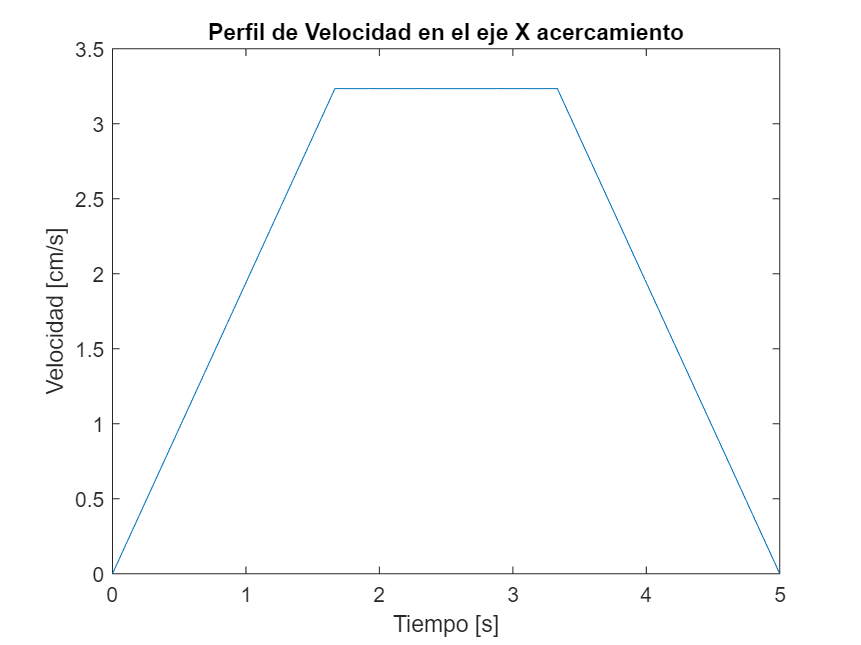


Px = 0.5*mX*t.^2-0.5*mX*((t-t1).^2).*(t>=t1)-0.5*mX*((t-2*t1).^2).*(t>=2*t1)+x20;

Py = 0.5*mY*t.^2-0.5*mY*((t-t1).^2).*(t>=t1)-0.5*mY*((t-2*t1).^2).*(t>=2*t1)+y20;

figure()
plot(t,Vx)
xlabel('Tiempo [s]')
ylabel('Velocidad [cm/s]')
title('Perfil de Velocidad en el eje X acercamiento')

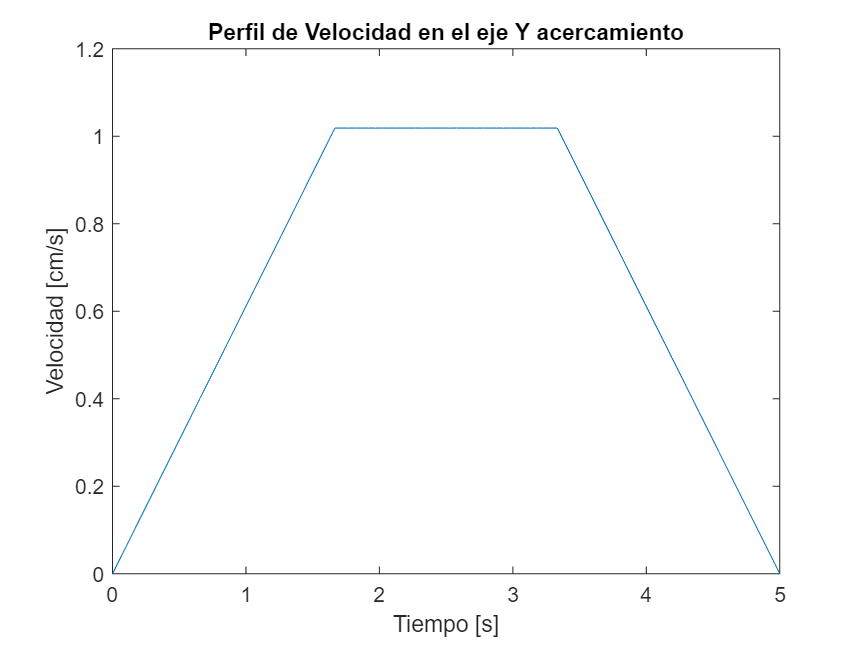


figure()
plot(t,Vy)
xlabel('Tiempo [s]')
ylabel('Velocidad [cm/s]')
title('Perfil de Velocidad en el eje Y acercamiento')

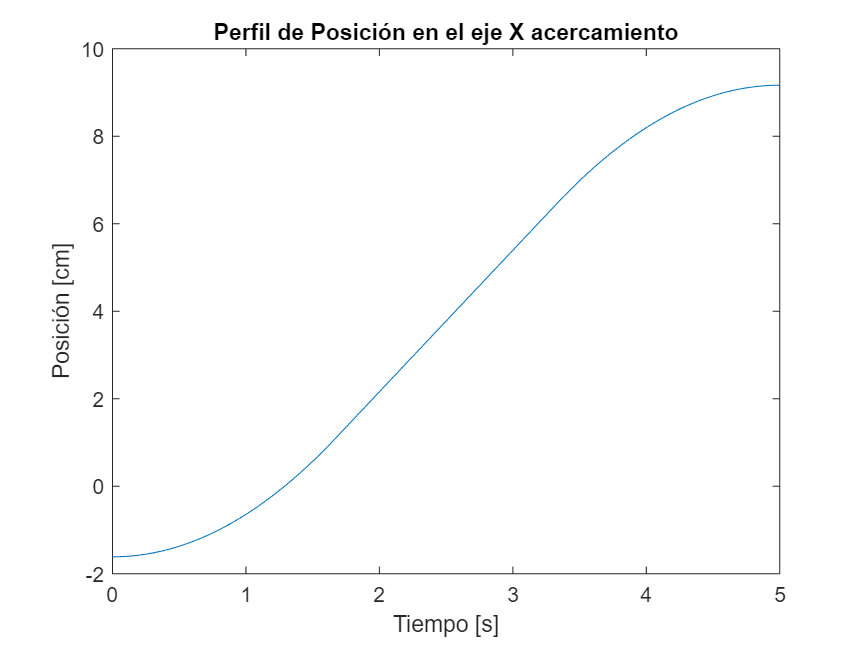


figure()
plot(t,Px)
xlabel('Tiempo [s]')
ylabel('Posición [cm]')
title('Perfil de Posición en el eje X acercamiento')

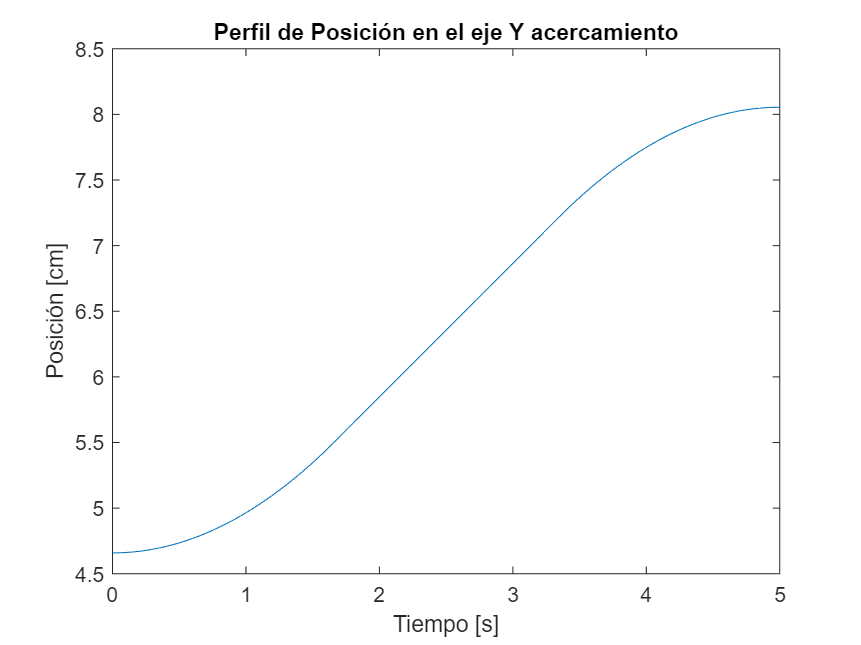


figure()
plot(t,Py)
xlabel('Tiempo [s]')
ylabel('Posición [cm]')
title('Perfil de Posición en el eje Y acercamiento')

## Visualización

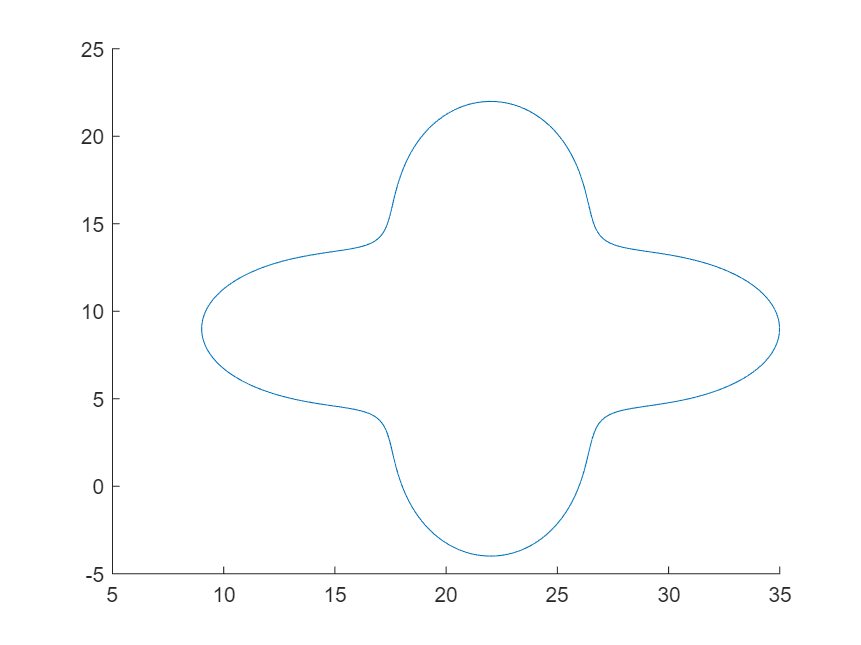

%Vectores de la posición distal del mecanismo en todo momento
XTotal = [Px, x(1,pos:end), x(1,1:pos-1)];
YTotal = [Py, y(1,pos:end), y(1,1:pos-1)];

%Cinematica inversa de todo el movimiento
q1 = zeros(1,length(XTotal));
q2 = zeros(1,length(YTotal));
figure(); %creamos la figura para visualizar
for i = 1:length(q1)
    %Cinematica inversa
    [q1(i), q2(i)] = Cinversa(l1,l2,XTotal(i),YTotal(i),q10,q20);
    q10 = q1(i);
    q20 = q2(i);
    %Gráfica
    cla;    %clear axes
    hold on
    plot(x,y);%Trebol base
    %Primer eslabon
    x1 = l1*cos(q1(i));
    y1 = l1*sin(q1(i));
    %Segundo eslabon
    x2 = XTotal(i);
    y2 = YTotal(i);
%     plot([0 x1],[0 y1],'rd-','LineWidth',3)
%     plot([x1 x2],[y1 y2],'bd-','LineWidth',3)
%     pause(0.00001);
%     xlim([-40 40]);
%     ylim([-40 40]);
end


% figure()
% hold on
% x1 = l1*cos(q1(end));
%     y1 = l1*sin(q1(end));
%     %Segundo eslabon
%     x2 = XTotal(end);
%     y2 = YTotal(end);
%     plot([0 x1],[0 y1],'rd-','LineWidth',3)
%     plot([x1 x2],[y1 y2],'bd-','LineWidth',3)

tt = tt+t(end);

tttt = zeros(1,1000);
q1a =  zeros(1,1000);
q2a =  zeros(1,1000);
delta = tt(2) - tt(1);
tttt(1) = tt(end);
q1a(1) = q1(end);
q2a(1) = q2(end);

for i = 2:length(tttt)
    tttt(i) = tttt(i-1) + delta;
    q1a(i) = q1a(i-1);
    q2a(i) = q2a(i-1);
end

ttt = [t tt tttt];
q1R = [q1 q1a];
q2R = [q2 q2a];


q1S = [(ttt')+5 (q1R')*(180/pi)];
q2S = [(ttt')+5 (q2R')*(180/pi)];


q1S(end,2)

ans = 108.6867

q2S(end,2)

ans = -141.2089

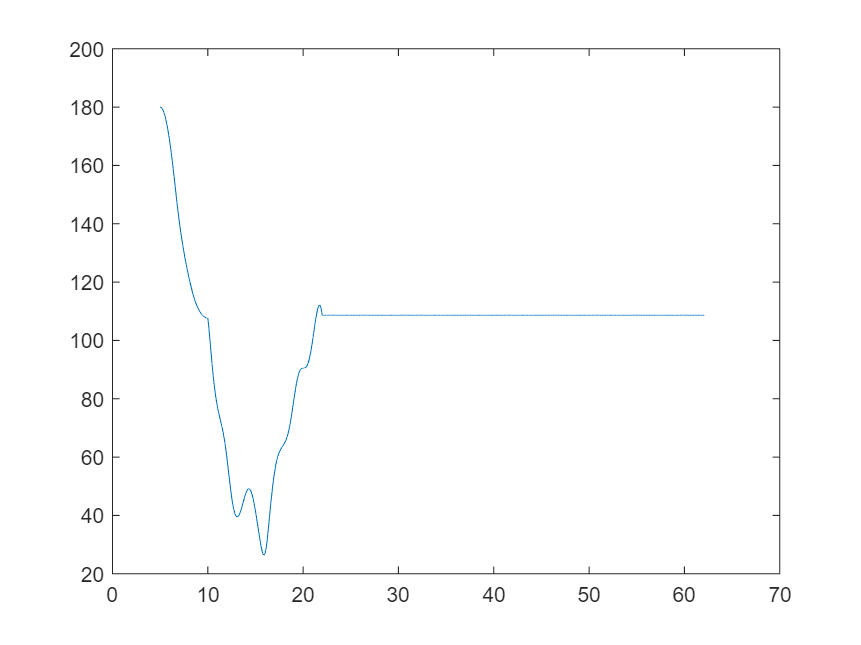


figure()
plot(q1S(:,1),q1S(:,2))

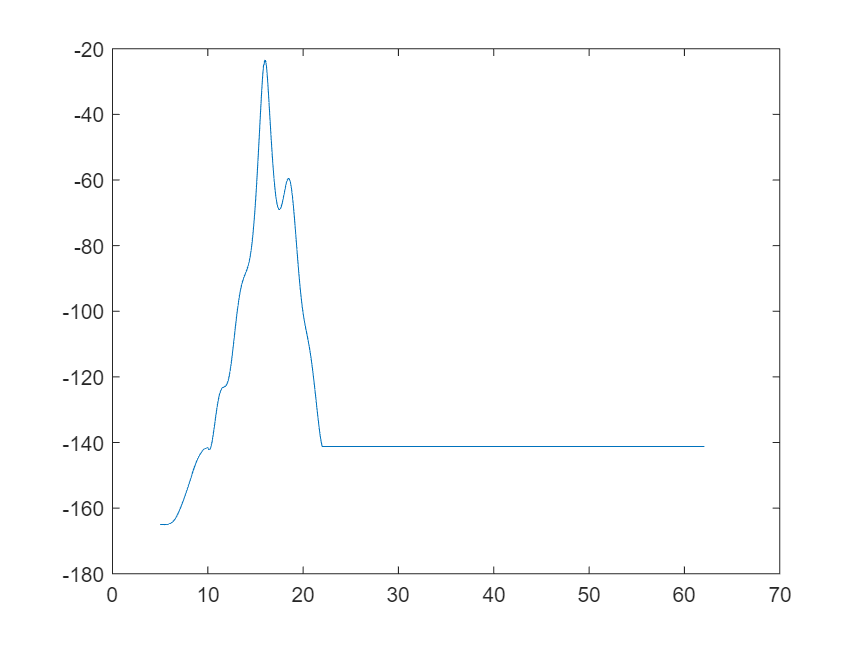


figure()
plot(q2S(:,1),q2S(:,2))